% Expected risk minimization with C classes
clear all, close all,

% Indicate if you want visualization plots
visualizationFlag = 1;% 0: no plots, 1: visualization plots

C = 3; % Number of classes
M = 4; % Number of Gaussian components
N = 1000; % Number of samples
n = 3; % Data dimensionality (must be 2 for plots to work)

% Specify loss-matrix for ERM classifier design
lossMatrix = ones(C,C)-eye(C); % Using 0-1 loss to minimize probability-of-error

% Specify the data pdf
gmmParameters.component2label = [1,2,3,3]; % This row vector indicates which Gaussian component belongs to which class
gmmParameters.priors = ones(1,M)/M; % uniform component priors
gmmParameters.meanVectors = repmat(2*gmmParameters.component2label,n,1)+1.25*n*M*rand(n,M); % arbitrary mean vectors
gmmParameters.numberOfClasses = C;
for m = 1:M
    A = eye(n)+0.2*randn(n,n);
    gmmParameters.covMatrices(:,:,m) = A'*A; % arbitrary covariance matrices
end
% Generate samples from specified data pdf
[x,componentLabels] = generateDataFromGMM_OG(N,gmmParameters,0); % Generate data
% Convert component labels to class labels for each sample
labels = zeros(1,N);
for m = 1:M
    indm = find(componentLabels == m);
    labels(1,indm) = repmat(gmmParameters.component2label(m),1,length(indm));
end
% Determine ERM decisions for each samples using specified (true) data PDF
for l = 1:C
    components{l} = find(gmmParameters.component2label==l)
    classPriors(l,1) = sum(gmmParameters.priors(components{l}))
    tempP = gmmParameters.priors(components{l})/classPriors(l,1)
    tempMU = gmmParameters.meanVectors(:,components{l})'
    tempSIGMA = gmmParameters.covMatrices(:,:,components{l})
    classConditionalPDF{l} = gmdistribution(tempMU,tempSIGMA,tempP)
end

components = 1×1 cell array
    {[1 2]}


classPriors = 0.2857

tempP =     0.5000    0.5000


tempMU =    17.7044    7.9137
    4.9119    5.2172


tempSIGMA = tempSIGMA(:,:,1) =

    1.5857    0.1455
    0.1455    1.3347


tempSIGMA(:,:,2) =

    0.9703   -0.1379
   -0.1379    0.9576


classConditionalPDF = 1×1 cell array
    {1×1 gmdistribution}


components = 1×2 cell array
    {[1 2]}    {[3 4]}


classPriors =     0.2857
    0.2857


tempP =     0.5000    0.5000


tempMU =     7.5733    6.6419
   21.1950   10.3546


tempSIGMA = tempSIGMA(:,:,1) =

    1.0722    0.2791
    0.2791    1.2884


tempSIGMA(:,:,2) =

    1.2336    0.3963
    0.3963    1.0509


classConditionalPDF = 1×2 cell array
    {1×1 gmdistribution}    {1×1 gmdistribution}


components = 1×3 cell array
    {[1 2]}    {[3 4]}    {[5 6 7]}


classPriors =     0.2857
    0.2857
    0.4286


tempP =     0.3333    0.3333    0.3333


tempMU =     6.1841   19.7773
    7.8395    7.4904
    7.8230   14.1444


tempSIGMA = tempSIGMA(:,:,1) =

    1.5692    0.6204
    0.6204    0.9297


tempSIGMA(:,:,2) =

    1.0598   -0.0188
   -0.0188    0.4795


tempSIGMA(:,:,3) =

    1.0865   -0.0138
   -0.0138    1.0876


classConditionalPDF = 1×3 cell array
    {1×1 gmdistribution}    {1×1 gmdistribution}    {1×1 gmdistribution}


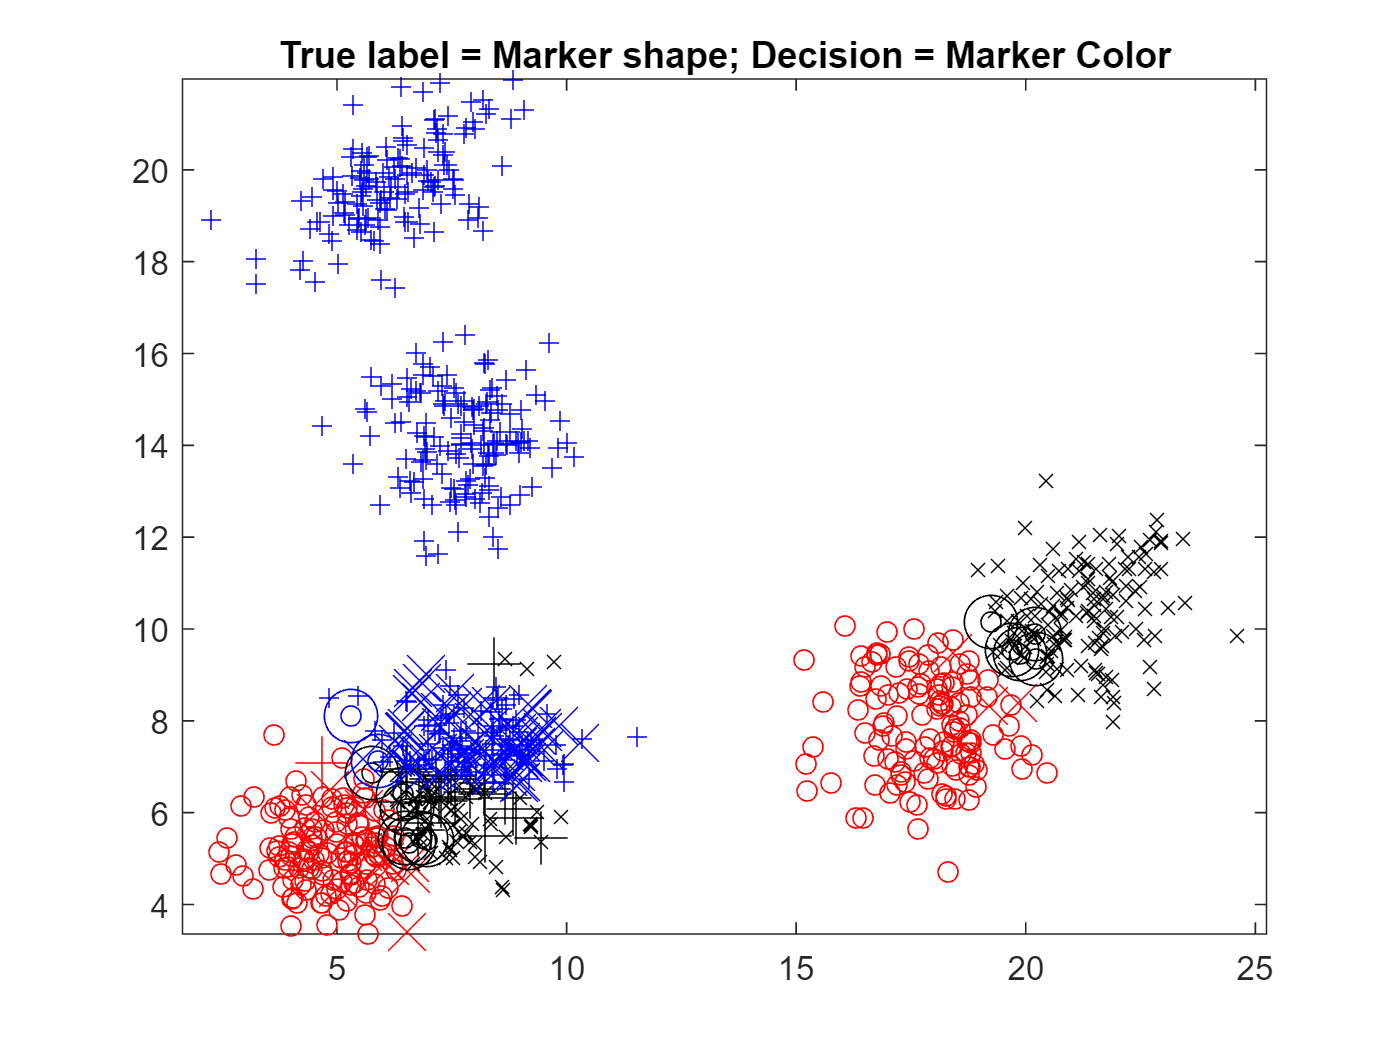

[n,N] = size(x);
% Evaluate class conditional likelihoods p(x|L=l) for each sample-label pair.
for l = 1:C
    %pxgivenl(l,:) = evalGaussianPDF(x,gmmParameters.meanVectors(:,l),gmmParameters.covMatrices(:,:,l)); 
    pxgivenl(l,:) = pdf(classConditionalPDF{l},x');
end
%determine the overall data pdf
classConditionalPDFTotal = gmdistribution(gmmParameters.meanVectors',gmmParameters.covMatrices,gmmParameters.priors);

% Evaluate the likelihood of each sample according to the overall data pdf
%px=classPriors'*pxgivenl;
px = pdf(classConditionalPDFTotal,x')';%pdf(gmmParameters,x); % Note that gmmParameters is a mixture of class-conditional GMMs
% Evaluate the class posterior probabilities for each label-sample pair
classPosteriors = pxgivenl.*repmat(classPriors,1,N)./repmat(px,C,1); % P(L=l|x)
% Evaluate expected risk (loss) values for each decision-sample pair
expectedRisks = lossMatrix*classPosteriors; % Expected Risk for each label (rows) for each sample (columns)
% Determine minimum-expected-risk decisions for each sample
[~,decisions] = min(expectedRisks,[],1); 
% Note: minimum expected risk decision with 0-1 loss is MAP classification
% and minimizes probability of error

% Estimate the confusion matrix P(D=d|L=l) from samples for each
% decision-label pair
mShapes = 'ox+*.'; % Accomodates up to C=5
mColors = 'rkbmy';
if visualizationFlag==1 & 0<n & n<=3
    figure(1), clf,
end 
for d = 1:C % each decision option
    for l = 1:C % each class label
        ind_dl = find(decisions==d & labels==l);
        confusionMatrix(d,l) = length(ind_dl)/length(find(labels==l));
        if visualizationFlag==1 & 0<n & n<=3
            figure(1), 
            plot(x(1,ind_dl),x(2,ind_dl),strcat(mShapes(l),mColors(d))), 
            hold on, axis equal,
            title('True label = Marker shape; Decision = Marker Color')
            if d~=l
                plot(x(1,ind_dl),x(2,ind_dl),strcat(mShapes(l),mColors(d)),'Markersize',16),
            end
        end
    end
end